# Ejercicio Dos

## Valores de Entrada

Esta es la lista que almacena las dimensiones de los filtros que se usarán en todo el desarrollo

filterValues = [3, 5, 7, 11];

#### Rutas 

Rutas de cada imagen que se manipula en el programa.

root = 'images/granos.png';     % Se aplica a los puntos uno, dos y seis.
root03 = 'images/granos.png';       % Ejercicio filtro mediana 
root04 = 'images/tungsten_2.jpg';   % Ejercicio filtro Prewitt y sobel
root05 = 'images/Moon.tif';         % Ejercicio filtro Laplaciano

#### Tipos de Ruido 

noiseType = 'salt & pepper';        % Se aplica a los puntos uno y dos.
noiseType04 = 'gaussian';           % Se aplica para el punto cuatro (unsharp masking)

#### Mascaras Paso Bajas 

Dada una lista de valores, se crean filtros cuadrados con el mismo valor almacenado en cada celda

quantityFilters = length(filterValues);
filters = cell(1,length(filterValues));
for i = 1:length(filterValues)
    filter = ones(filterValues(i), filterValues(i)) / (filterValues(i)^2);
    filters{i} = filter;
end

#### Mascaras con valores gaussianos

Dada una lista de valores, se crean filtros cuadrados con valores gaussianos que varian según la dimensión del filtro

gaussianFilters = cell(1,length(filterValues));
for i = 1:length(filterValues)
    gaussianFilters{i} = creatGaussianFilters(i);
end

#### Valores para ajusta el laplaciano

limitsLapaImage = [60/255 200/255]; 

## Ejercicios

### Imagenes

Se muestra la imagen original acompañada de una versión con ruido.

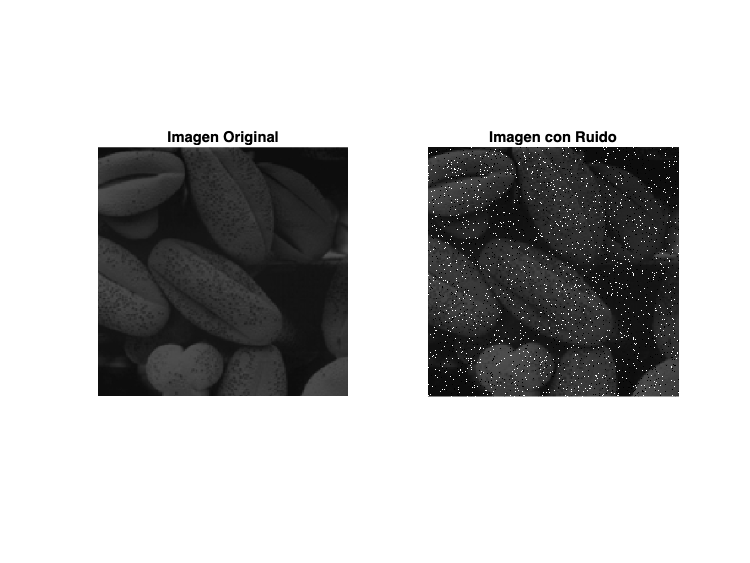

orginalImage = imread(root);
noisyImage = imnoise(orginalImage,noiseType);
showImages({orginalImage,noisyImage},{'Imagen Original', 'Imagen con Ruido'});

### Filtros paso bajas promedio estándar 

Aplicar los filtros paso bajas promedio est ́andar a la imagen sin ruido y a la imagen con ruido usando filtros de orden 3x3, 5x5, 7x7 y 11x11. 						

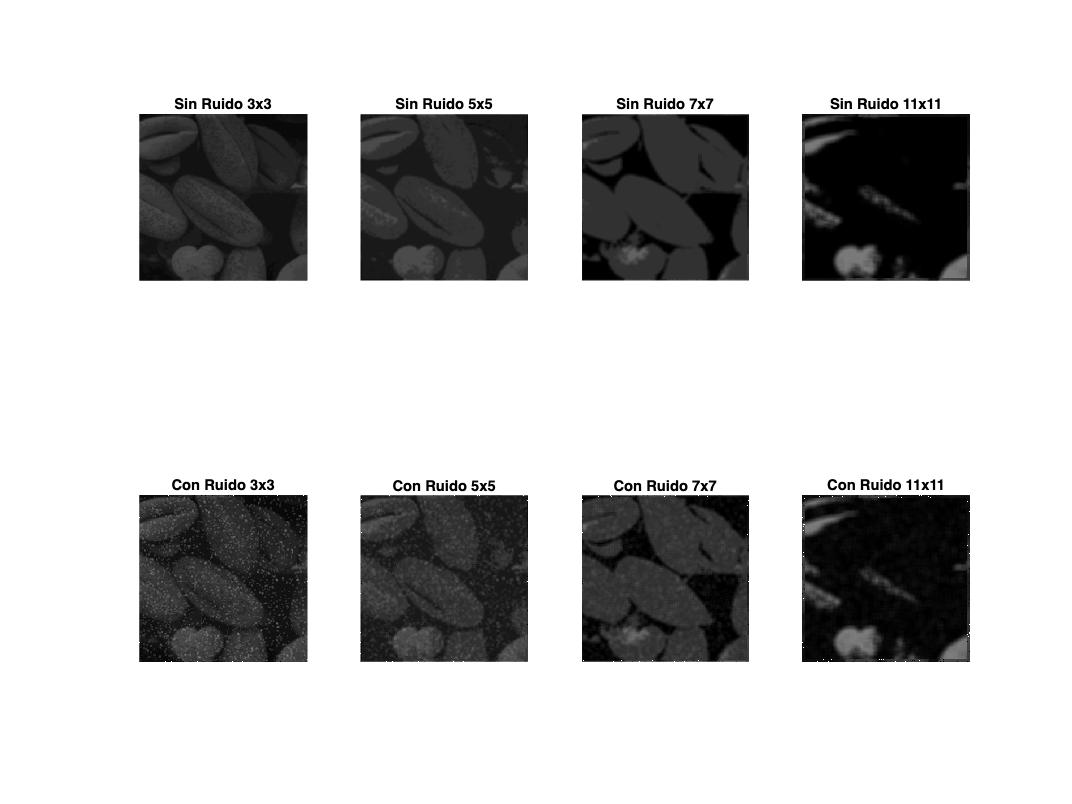

cleanImages01 = cell(2, quantityFilters);
for i = 1:quantityFilters
    cleanImages01{1,i} = aplyFilterTypeOne(orginalImage,filters{i},@pasoBaja);
    cleanImages01{2,i} = aplyFilterTypeOne(noisyImage,filters{i},@pasoBaja);
end
showCellImages(cleanImages01,filterValues,{'Sin Ruido', 'Con Ruido'});

### Filtros paso bajas promedio ponderado 

Aplicar los filtros paso bajas promedio ponderado a la imagen sin ruido y a la imagen con ruido usando filtros de orden 3x3, 5x5, 7x7 y 11x11	 

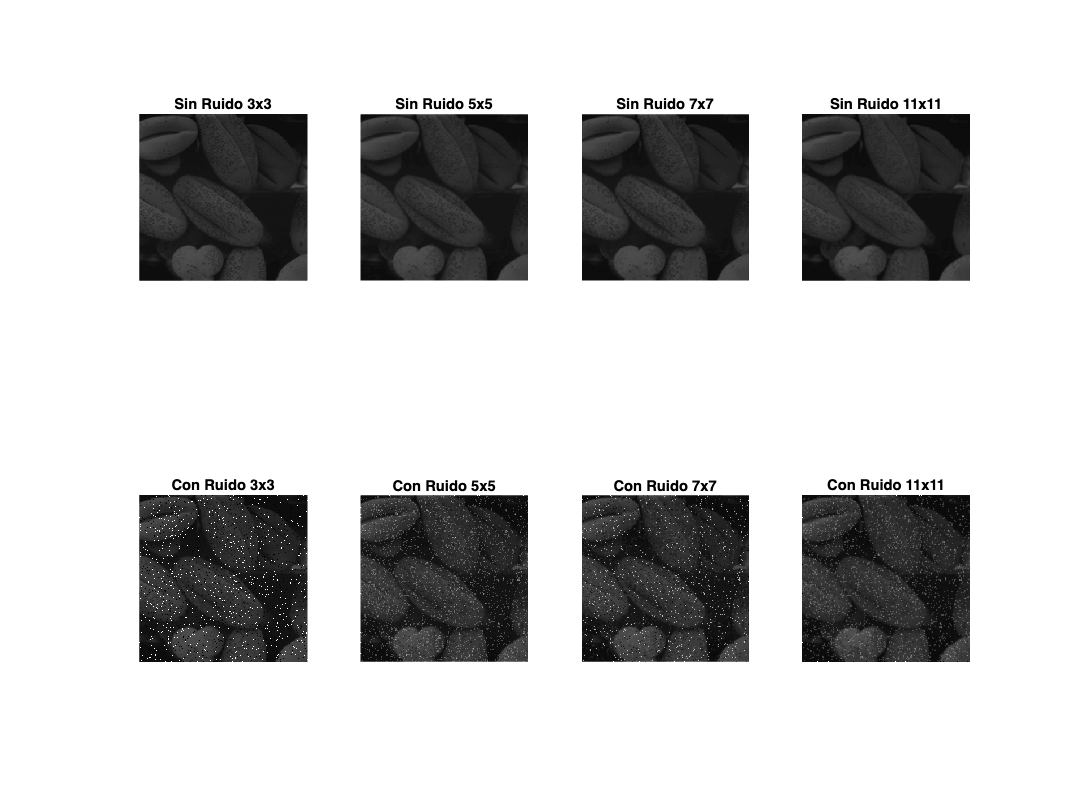

cleanImages02 = cell(2, quantityFilters);

for i = 1:quantityFilters
    cleanImages02{1,i} = aplyFilterTypeOne(orginalImage,gaussianFilters{i},@pasoBaja);
    cleanImages02{2,i} = aplyFilterTypeOne(noisyImage,gaussianFilters{i},@pasoBaja);
end
showCellImages(cleanImages02,filterValues,{'Sin Ruido', 'Con Ruido'});

### Filtro mediana

orginalImage03 = imread(root03);
noisyImage03 = imnoise(orginalImage03,noiseType);

`Aplicar a la imagen con ruido el filtro mediana de 3x3, 5x5, 7x7 y 11x11. Utilizar ruido ’sal y pimienta’ y ’gaussiano’. Compararlos. `

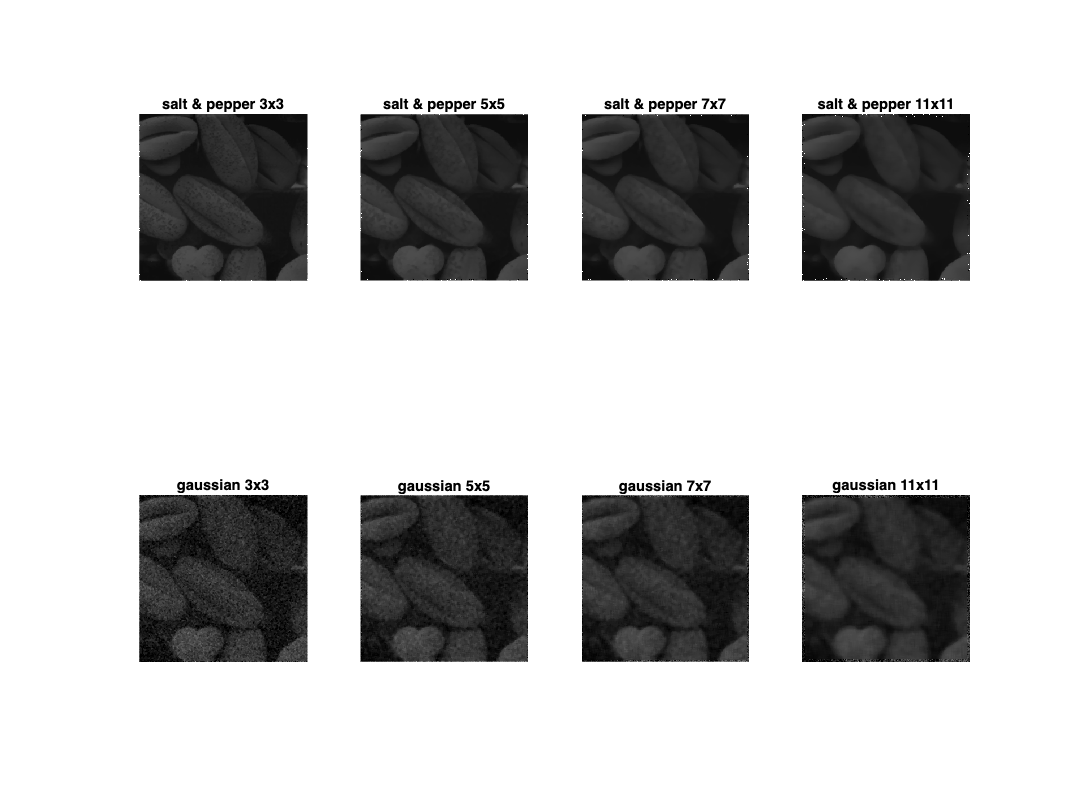

saltAndPepper03 = imnoise(orginalImage03,'salt & pepper');
gaussian03 = imnoise(orginalImage03,'gaussian');
cleanImages03 = cell(2, quantityFilters);
for i = 1:quantityFilters
    cleanImages03{1,i} = aplyFilter(saltAndPepper03,filters{i},@medium);
    cleanImages03{2,i} = aplyFilter(gaussian03,filters{i},@medium);
end
showCellImages(cleanImages03,filterValues,{'salt & pepper', 'gaussian'});

### Primera Derivada

Aplicar a la imagen sin ruido y con ruido los filtros basados en la primera derivada o detectores de borde siguientes

orginalImage04 = imread(root04);
noisyImage04 = imnoise(orginalImage04,noiseType04);

#### Prewitt

Prewitt en la direcci ́on X y en la direcciónn Y, asi como su magnitud. 						

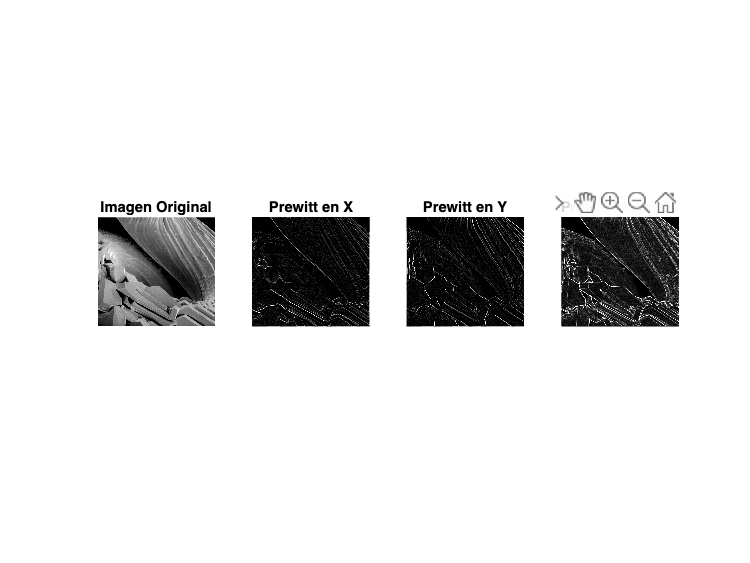

maskX = [1 1 1; 0 0 0; -1 -1 -1]; % Mascara X de prewitt
maskY = [1 0 -1; 1 0 -1; 1 0 -1]; % Mascara Y de prewitt
prewittMasks = {maskX, maskY};
prewittImage01 = applyFirstDerivative(orginalImage04,prewittMasks);
prewittImage02 = applyFirstDerivative(noisyImage04,prewittMasks);
showMultipleImages(prewittImage01,{'Imagen Original','Prewitt en X', 'Prewitt en Y', 'Prewitt Magnitud'});

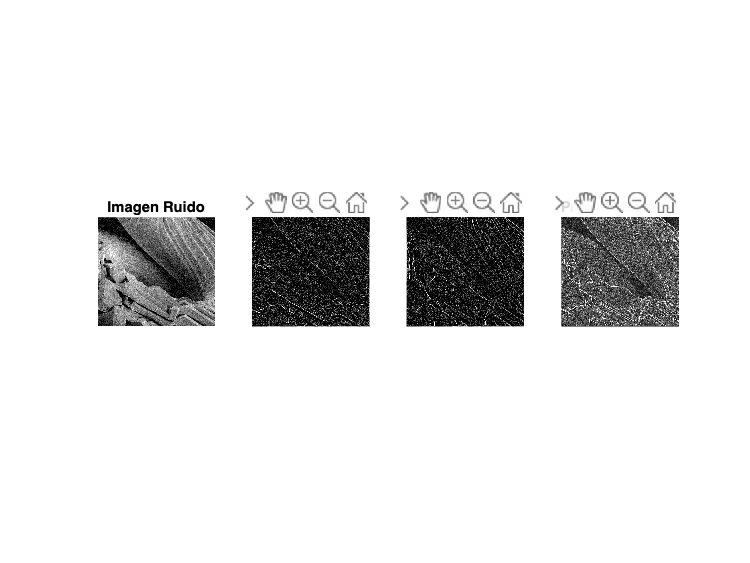

showMultipleImages(prewittImage02,{'Imagen Ruido','Prewitt en X', 'Prewitt en Y', 'Prewitt Magnitud'});

#### Sobel

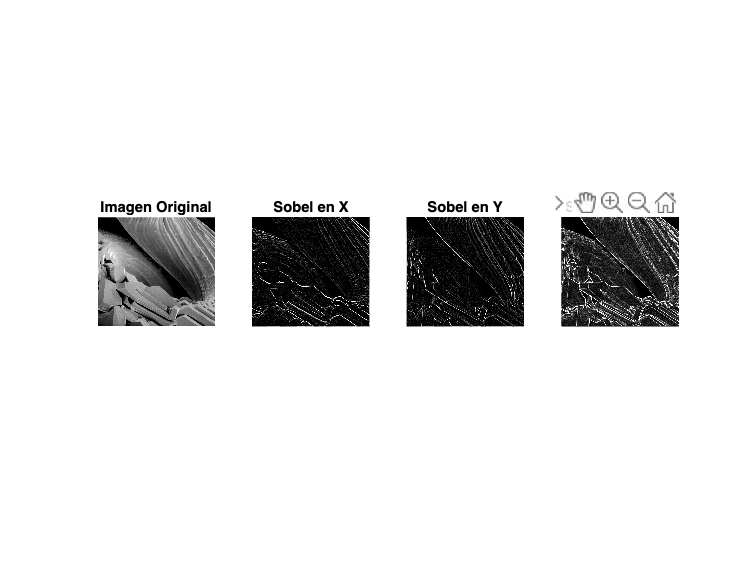

maskX = [-1 -2 -1; 0 0 0; 1 2 1]; % Mascara Y de sobel
maskY = [-1 0 1; -2 0 2; -1 0 1]; % Mascara X de sobel
sobelMasks = {maskX, maskY};
sobelImage01 = applyFirstDerivative(orginalImage04, sobelMasks);
sobelImage02 = applyFirstDerivative(noisyImage04, sobelMasks);
showMultipleImages(sobelImage01,{'Imagen Original','Sobel en X', 'Sobel en Y', 'Sobel Magnitud'});

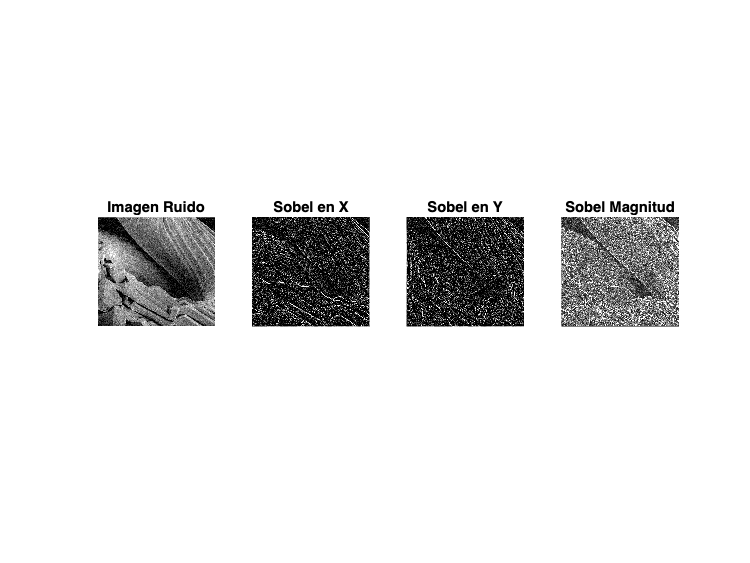

showMultipleImages(sobelImage02,{'Imagen Ruido','Sobel en X', 'Sobel en Y', 'Sobel Magnitud'});

### Laplaciano

Aplicar a una imagen el realce basado en las segundas derivadas (Laplaciano). Isotrópicos a 45 grados así como a 90 grados	 

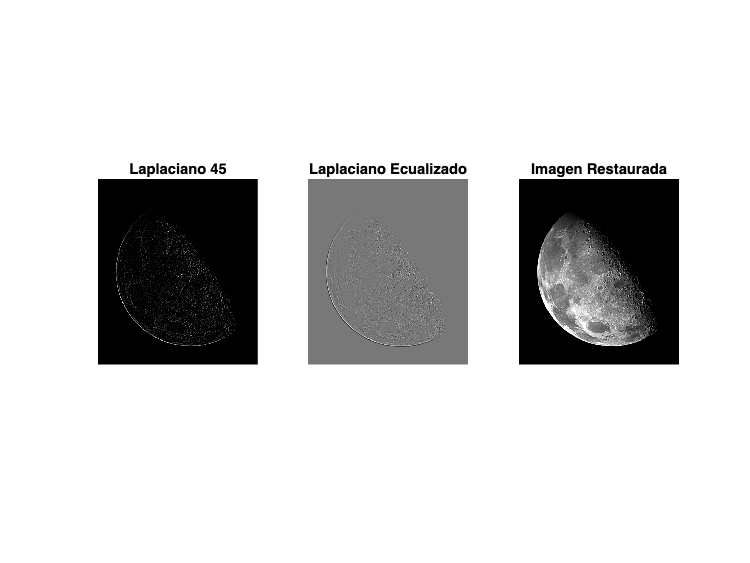

orginalImage05 = im2double(imread(root05)); 
lap45 = [-1 -1 -1; -1 8 -1; -1 -1 -1]; 
lap90 = [0 -1 0; -1 4 -1; 0 -1 0];

lapImages45 = aplyLapla(orginalImage05,lap45,limitsLapaImage);
lapImages90 = aplyLapla(orginalImage05,lap90,limitsLapaImage);

showMultipleImages(lapImages45, {'Laplaciano 45','Laplaciano Ecualizado', 'Imagen Restaurada'});

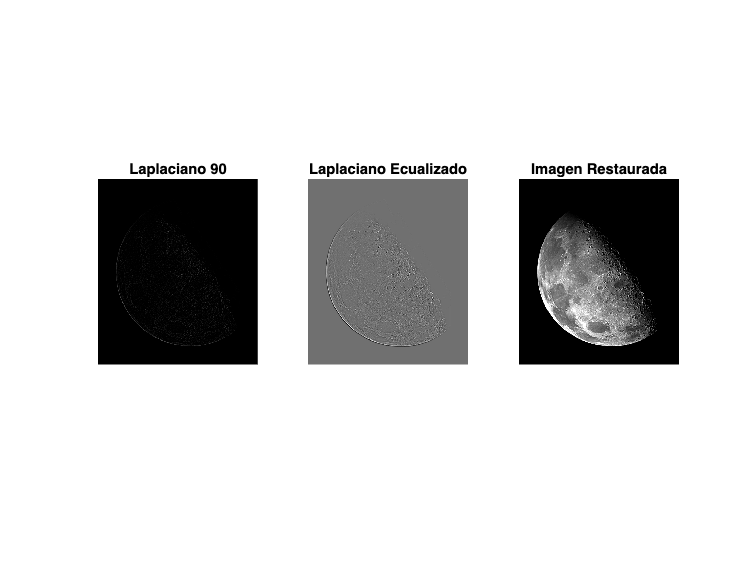

showMultipleImages(lapImages90, {'Laplaciano 90','Laplaciano Ecualizado', 'Imagen Restaurada'});

### unsharp masking

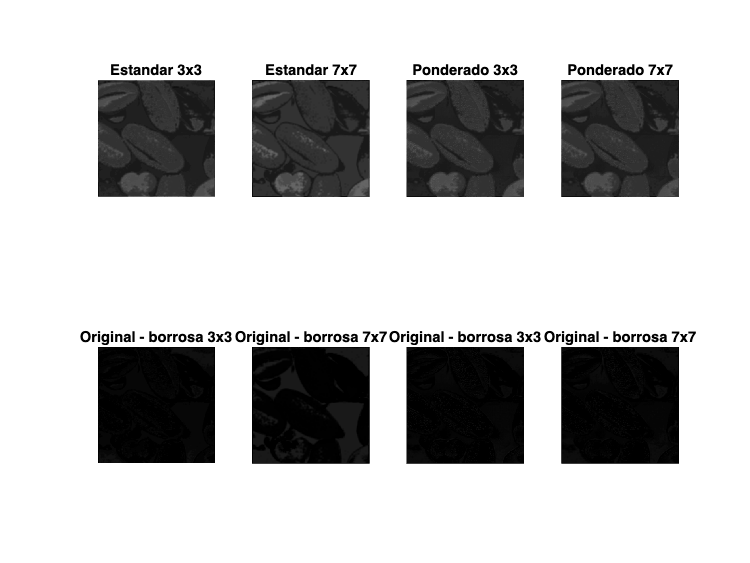

originalImage06 = cleanImages01{1,2};  % Sin ruido de paso bajas 5x5
noisyImage06 = cleanImages01{2,2};     % Con ruido de paso bajas 5x5
constantUnsharp = 1;
% Mandamos como parametro imagenes paso bajas promedio estandar,
% ponderado,imagen sin ruido y constante.
showUnsharp(cleanImages01,cleanImages02,originalImage06,constantUnsharp);

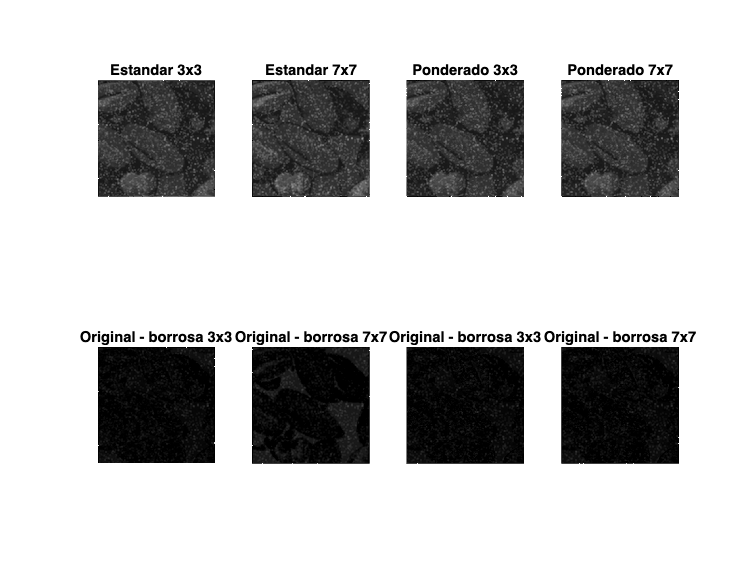

% Mandamos como parametro imagenes paso bajas promedio ponderado,
% ponderado,imagen sin ruido y constante.
showUnsharp(cleanImages01,cleanImages02,noisyImage06,constantUnsharp);

#### showUnsharp

function showUnsharp(standarImages, weightedImages, image, k)
    standar01 = image - standarImages{1,1};
    standar33 = image + (k*standar01);

    standar02 = image - standarImages{1,3};
    standar77 = image + (k*standar02);

    weighted01 = image - weightedImages{1,1};
    weighted33 = image + (k*weighted01);
    
    weighted02 = image - weightedImages{1,3};
    weighted77 = image + (k*weighted02);

    figure;
    subplot(2, 4, 1);
    imshow(standar33);
    title('Estandar 3x3');

    subplot(2, 4, 2);
    imshow(standar77);
    title('Estandar 7x7');

    subplot(2, 4, 3);
    imshow(weighted33);
    title('Ponderado 3x3');
    subplot(2, 4, 4);
    imshow(weighted77);
    title('Ponderado 7x7');

    subplot(2, 4, 5);
    imshow(standar01);
    title('Original - borrosa 3x3');

    subplot(2, 4, 6);
    imshow(standar02);
    title('Original - borrosa 7x7');

    subplot(2, 4, 7);
    imshow(weighted01);
    title('Original - borrosa 3x3');

    subplot(2, 4, 8);
    imshow(weighted02);
    title('Original - borrosa 7x7');
end 

## Funciones

#### creatGaussianFilters

function gaussianFilter = creatGaussianFilters(n)
    gaussianFilter = zeros(n, n);
    center = (n+1)/2;    % Se asume que los valores son impares
    sigma = n / 6;       % Desviación

    for i = 1:n
        for j = 1:n
            x = i - center;
            y = j - center;
            gaussianFilter(i, j) = exp(-(x^2 + y^2) / (2 * sigma^2)) / (2 * pi * sigma^2);
        end
    end

    gaussianFilter = gaussianFilter / sum(gaussianFilter(:)); % La suma siempre debe ser uno, este se normaliza
end

#### aplyFilter

Se proporciona una función genérica que acepta tres parámetros: una imagen a manipular, una máscara y una función que se encarga de evaluar la máscara utilizando submatrices de la imagen

function newImage = aplyFilter(image, filter, func)
    filterSize = size(filter);
    [n, m] = size(image);
    newImage = image;
    r = n - filterSize + 1; 
    c = m - filterSize + 1;
    halfFilter = floor(filterSize/2);
    for i = 1:r
    for j = 1:c 
        submatrix = image(i:i+filterSize-1, j:j+filterSize-1);
        newImage(i+halfFilter,j+halfFilter) = func(submatrix);
    end
    end
end

#### aplyFilterTypeOne

Se proporciona una función genérica que recibe tres parámetros: una imagen a manipular, una máscara y una función que se encarga de evaluar la máscara utilizando submatrices de la imagen. A diferencia de aplyFilter, la función que recibe como parametro puede acceder a los valores del filtro.

function newImage = aplyFilterTypeOne(image, filter, func)
    filterSize = size(filter);
    [n, m] = size(image);
    newImage = image;
    r = n - filterSize + 1; % Numero de filas y columnas
    c = m - filterSize + 1;
    halfFilter = floor(filterSize/2);
    for i = 1:r
    for j = 1:c 
        submatrix = image(i:i+filterSize-1, j:j+filterSize-1);
        newImage(i+halfFilter,j+halfFilter) = func(submatrix, filter);
    end
    end
end


#### pasoBaja

Se proporciona una función que toma como entrada una submatriz y una máscara, devuelve el valor estándar asociado a esa combinación. 

function standarValue = pasoBaja(submatrix, filter)
    standarValue = 0;
    [m, n] = size(submatrix);
    for i = 1:m
        for j = 1:n 
            submatrix(i, j) = submatrix(i, j) * filter(i, j);
            standarValue = standarValue + submatrix(i, j);
        end
    end
end

#### medium

Se proporciona una función que toma como entrada una submatriz, devuelve la mediana de los valores del subarreglo. 

function mediumValue = medium(submatrix)
    n = size(submatrix,1); 
    values = submatrix(:); 
    values = sort(values);     
    mediumValue = values((n^2+1)/2); 
end

#### applyFirstDerivative

function resultImages = applyFirstDerivative(originalImage, masks)
    resultImages = cell(1, 4);
    [n, m] = size(originalImage);
    newImage = uint8(zeros(n, m));
    maskX = masks{1};
    maskY = masks{2}; 

    for i = 1:n - 2
    for j = 1:m - 2 
        Gx = sum(sum(maskX.* double(originalImage(i:i+2, j:j+2)))); 
        Gy = sum(sum(maskY.* double(originalImage(i:i+2, j:j+2)))); 
        newImage(i+1, j+1) = sqrt(Gx.^2 + Gy.^2); % Magnitud, quitar raiz
    end
    end

    resultImages{1} = originalImage;
    resultImages{2} = aplyFilterTypeOne(originalImage,maskX, @multiplyMatrix);
    resultImages{3} = aplyFilterTypeOne(originalImage,maskY, @multiplyMatrix);
    resultImages{4} = newImage;
end

#### aplyLapla

function lapImages = aplyLapla(image, filter, limits)
    lapImages = cell(1, 3);

    % Imagen con transformación logaritmica
    lapImage01 = aplyFilterTypeOne(image,filter,@multiplyMatrix);

    % se hace la transformación logaritmica normalizanda
    minValue = min(lapImage01(:));
    maxValue = max(lapImage01(:));

    lapImage02 = (lapImage01 - minValue) / (maxValue - minValue);

    % Imagen con transformación logaritmica normalizanda
    sharpenedImage = image + lapImage02;

    % Normalizando los valores de sharpenedImage
    minValue = min(sharpenedImage(:)); 
    maxValue = max(sharpenedImage(:));
    sharpenedImage = (sharpenedImage - minValue) / (maxValue - minValue);
    sharpenedImage = imageAdjust(sharpenedImage, limits);

    lapImages{1,1} = lapImage01;
    lapImages{1,2} = lapImage02;
    lapImages{1,3} = sharpenedImage;

end


#### multiplyMatrix

function newValue = multiplyMatrix(newMatrix, filter)
    newValue = sum(sum(double(filter) .* double(newMatrix)));
end

#### imageAdjust

function newImage = imageAdjust(image, limits)
    newLimits = [0 1];
    [m, n] = size(image);
    newImage = zeros(m, n);

    minLimit = limits(1); % en este caso es de 60
    maxLimit = limits(2); % en este caso es de 200 

    for row = 1:m
    for col = 1:n  
        oldValue = image(row, col);
        oldValue = oldValue - minLimit;  
        oldValue = oldValue/(maxLimit - minLimit);
        oldValue = oldValue*(newLimits(2) - newLimits(1)); 
        oldValue = oldValue + newLimits(1);
 
        oldValue = max(min(oldValue, newLimits(2)), newLimits(1)); % El nuevo valor será el maximo del 
          
        newImage(row, col) = oldValue;
          
    end
    end

end


#### showCellImages

function showCellImages(images,filterValues, image_labels)
    figure;
    numRows = 2;
    numCols = length(filterValues);
    for i = 1:numRows
    for j = 1:numCols
        imagen = images{i, j};
        subplot(numRows, numCols, (i-1)*numCols + j);
        imshow(imagen);
        title([image_labels{i}, ' ', num2str(filterValues(j)), 'x', num2str(filterValues(j))]);
    end
    end
    set(gcf, 'Position', [100, 100, 800, 600]);
end 

### showImages

Se pueden desplegar dos imagenes acompañadas de sus etiquetas

function showImages(images, image_labels)
    figure;
    subplot(1, 2, 1);
    imshow(images{1});
    title(image_labels{1});
    subplot(1, 2, 2);
    imshow(images{2});
    title(image_labels{2});
end


**showMultipleImages**

dado un conjunto de imagenes, se despliegan acompañadas de su etiqueta en una fila

function showMultipleImages(images, image_labels)
    num_images = numel(images);
    figure;
    for i = 1:num_images
        subplot(1, num_images, i);
        imshow(images{i});
        title(image_labels{i});
    end
end
